Q1(a)


format long e;
n=10;
x=randi([1,50],n,1);
W=tril(ones(n,n)*(-1),-1)+eye(n,n);
W(:,n)=ones(n,1);
b=W*x;
x1=W\b;
error=norm(x-x1,inf)/norm(x,inf);
disp(error)

     0



disp(cond(W))

     4.384972244913183e+00



Q1(b)

[Q,R]=qr(W);
x2=R\Q*b;
err1=norm(x-x2,inf)/norm(x,inf);
disp(err1)

     2.674248959604003e+00



Q1(c)

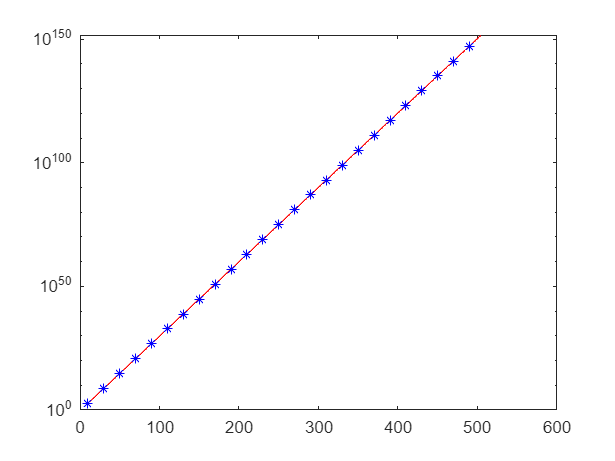

n=10:0.5:505;
x=2.^(n-1);
semilogy(n,x,'r');
hold on;
n=10:20:500;
m=length(n);
G=zeros(m,1);
for i=1:m
    w=Wilkinson(n(i));
    [L,U,p]=lu(w);
    G(i)=max(max(abs(U)))/max(max(abs(w)));
end
semilogy(n,G,'b*');
hold off;

Q1(d)

n=10:10:200

n =     10    20    30    40    50    60    70    80    90   100   110   120   130   140   150   160   170   180   190   200


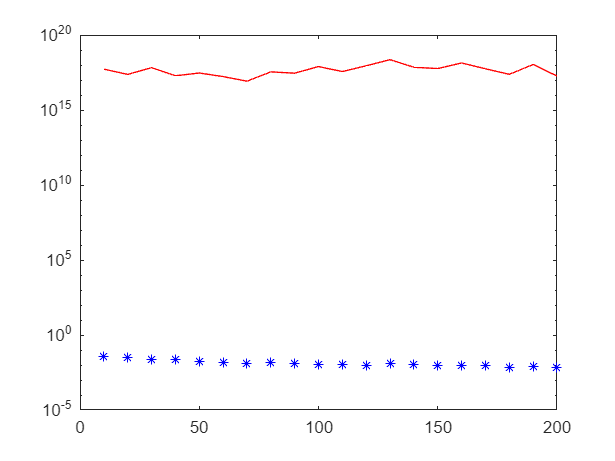

m=length(n);
pg=zeros(m,1);
cdn=zeros(m,1);
for i=1:m
    g_m=golub(n(i));
    cdn(i)=cond(g_m);
    [L,U]=GENP(g_m);
    pg(i)=max(max(abs(U)))/max(max(abs(g_m)));
end
semilogy(n,pg,'b*');
hold on;
semilogy(n,cdn,'r');
hold off;

function W=Wilkinson(n)
    W=tril(ones(n,n)*(-1),-1)+eye(n,n);
    W(:,n)=ones(n,1);
end

function A=golub(n)
    s=10;
    L=tril(round(s*randn(n)),-1)+eye(n);
    U=triu(round(s*randn(n)),1)+eye(n);
    A=L*U;
end
function [L, U] = GENP(A)
    [~, n] = size(A);
    for k = 1:n-1
        A(k+1:n,k) = A(k+1:n,k)/A(k,k);
        j = k+1:n;
        A(j,j) = A(j,j)-A(j,k)*A(k,j);
    end
    L = eye(n,n)+ tril(A,-1);
    U = triu(A); 
end